%%                 - Autonomous USV Path Planning Algorithm -                  %%
%    This code uses an algorithm based on the projection collision avoidance    %
%    method to find a path from the start point to the target point             %
%                         Adopts virtual waypoints                              %
%                                                                               %
%                Written by Dimitrios Stergianelis on August 2018               %
%                                                                               %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
% Clean the workspace and close the open figures
clear
clc
close all
tic;

## Parameters - Setting up the problem

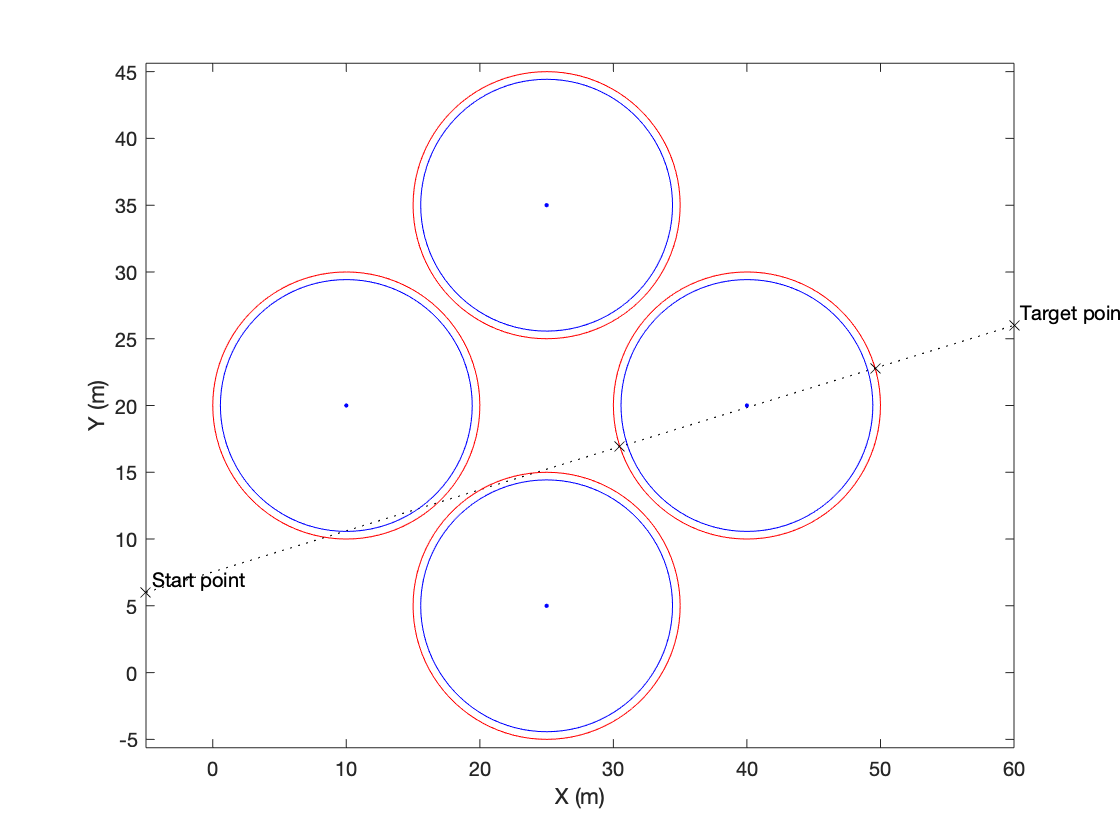

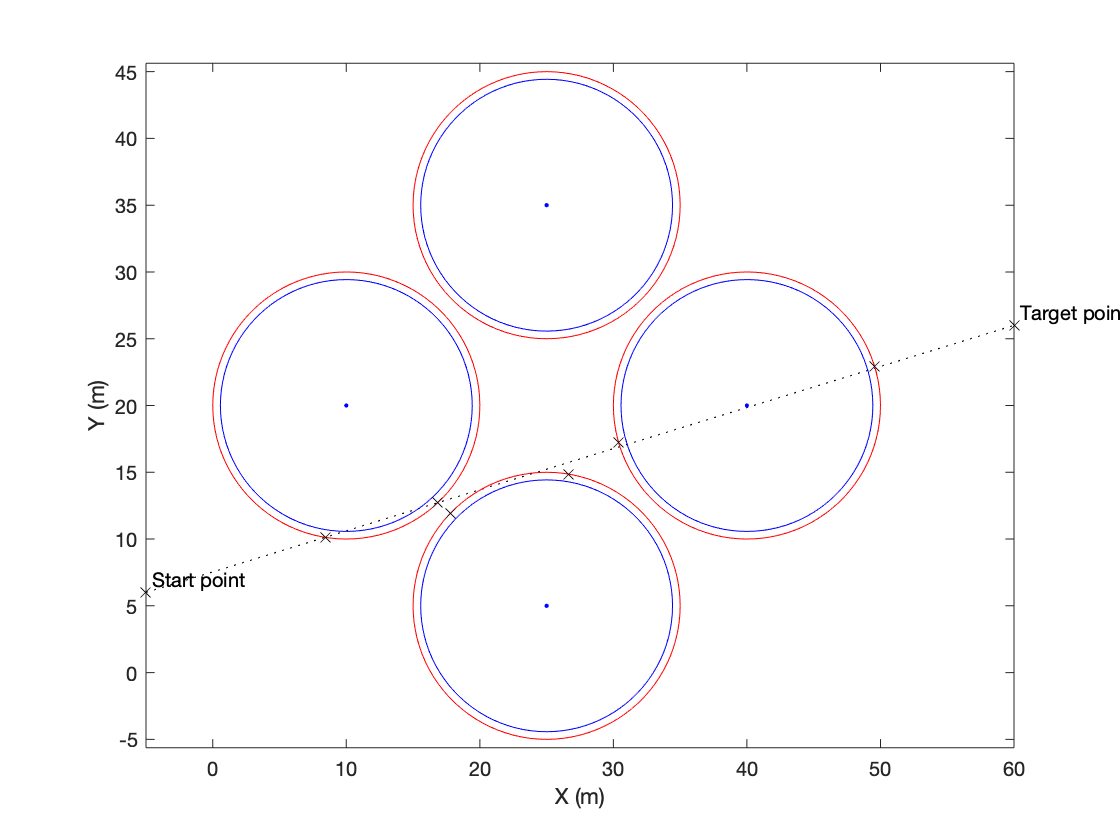

Error, algorithm did not converge.


% Start point S (XS, YS)
XS = -5;
YS = 6;
 
% Target point T (XT, YT)
XT = 60;
YT = 26;
 
% Obstacle representation: circle with centre at (XO, YO) and radius RO
XO = [10, 25, 25, 40];
YO = [20, 5, 35, 20];
RO = [9.429, 9.429, 9.429, 9.429];
 
% Safety radius RB
% Was set equal to the radius of the vessel region (RV), for the simulations
RB = 0.571;
 
% Number of obstacles N
N = length(XO);
min_x_array = zeros(1,N);
max_x_array = zeros(1,N);
min_y_array = zeros(1,N);
max_y_array = zeros(1,N);
solution_found = false;
 
[solution_found, err] = find_route(XS, YS, XT, YT, XO, YO, RO, RB, N);

Another try:


Intermediate point


    0.5710



     6



Finally


Straight-line Length: 5.571

Minimum Trajectory No. of segments: 1
Minimum Trajectory Length: 5.571

Simplified Trajectory No. of segments: 1
Simplified Trajectory Length: 5.571


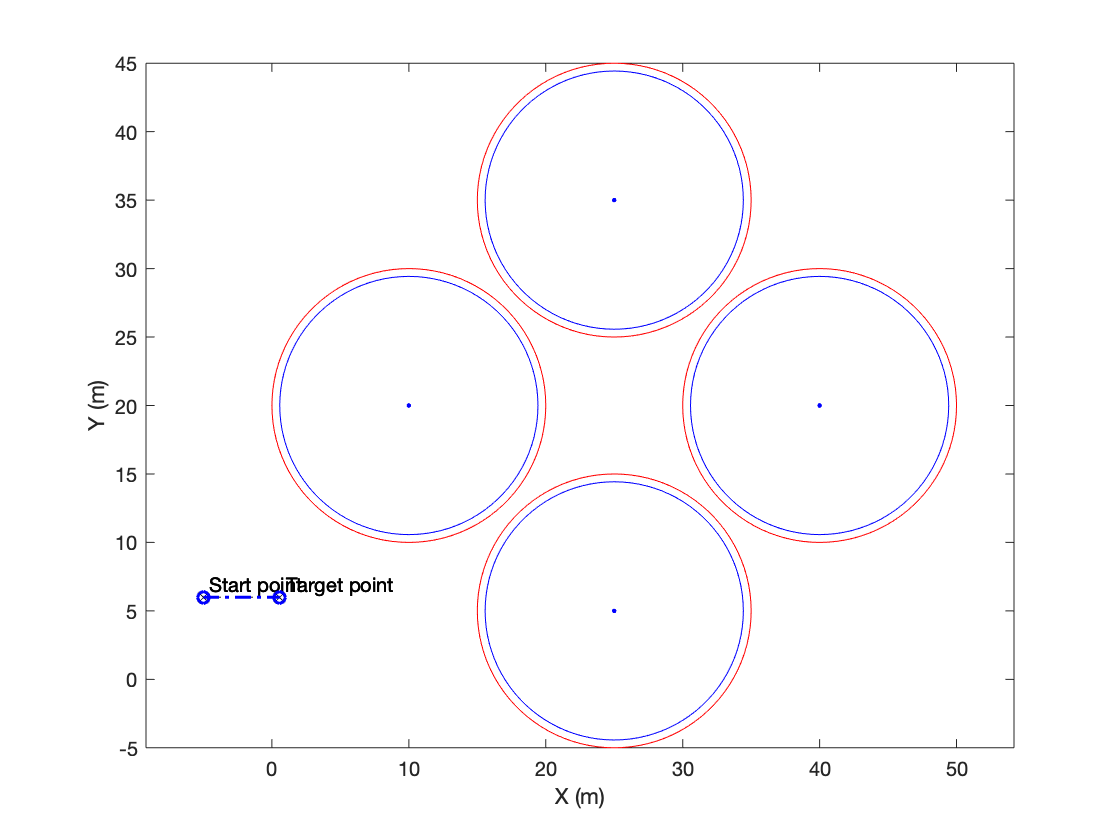

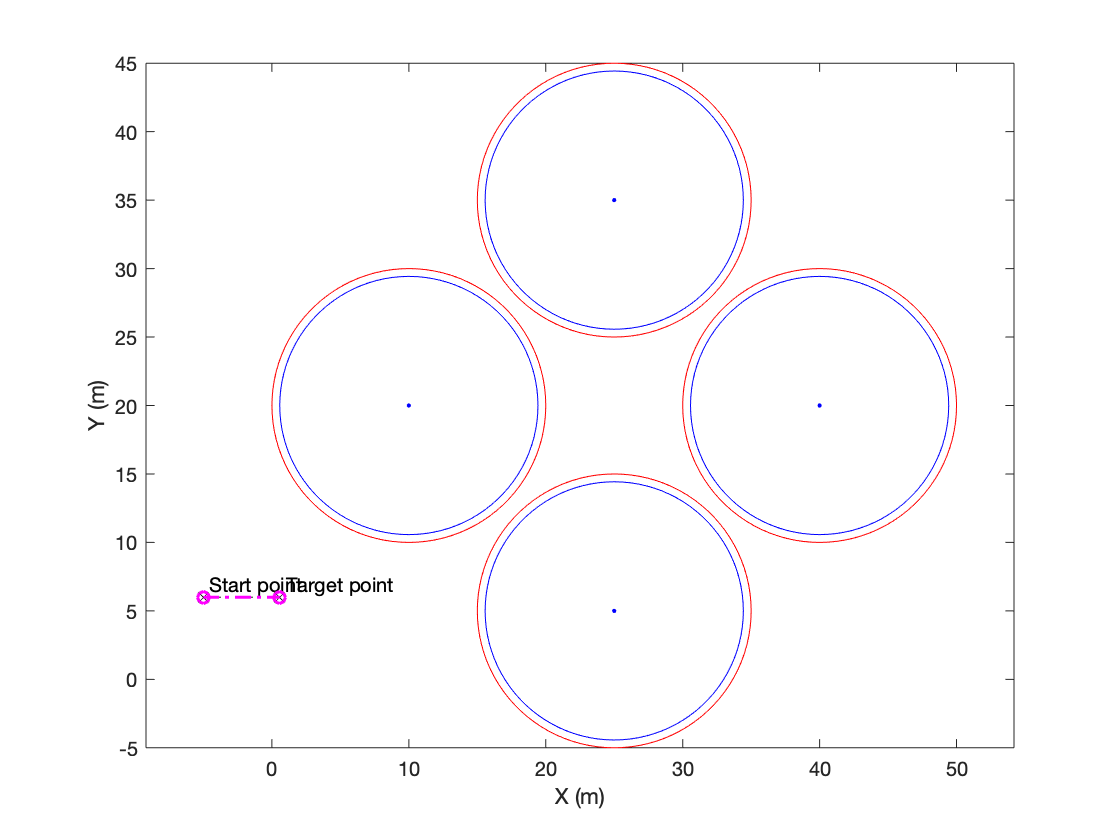

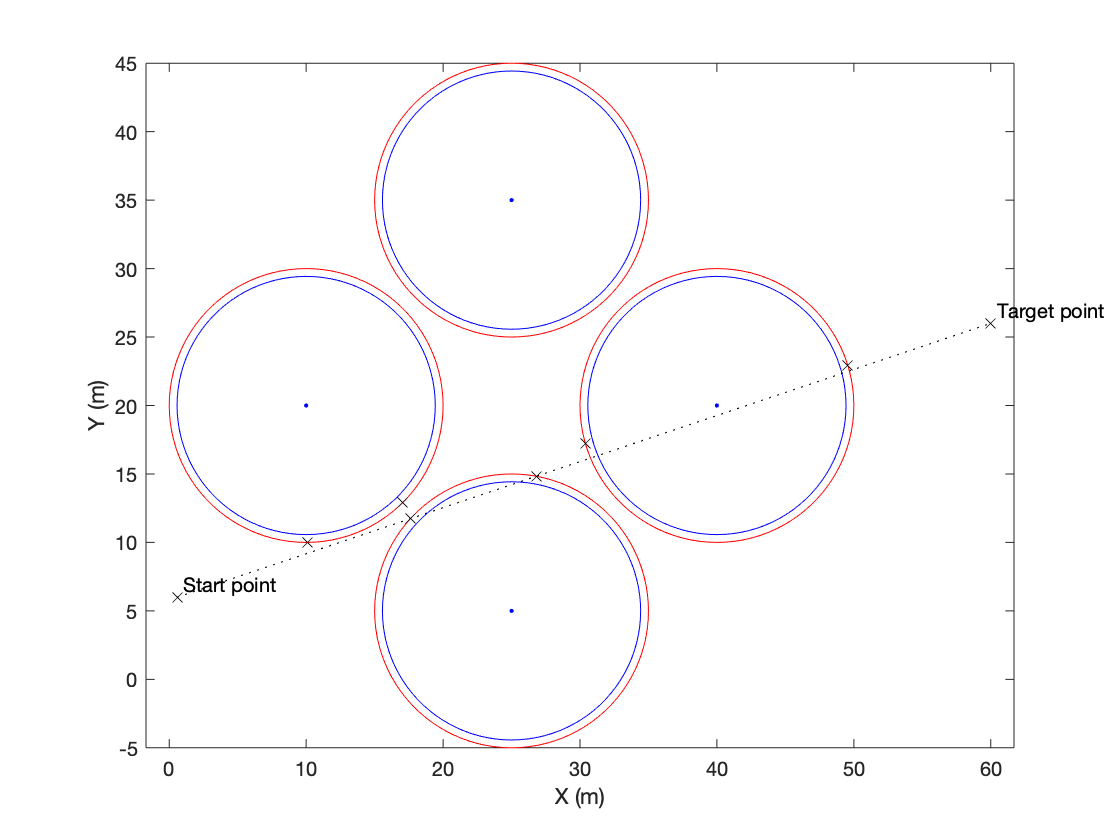

Error, algorithm did not converge.


Another try:


Intermediate point


   49.4290



     6



Finally


Straight-line Length: 54.429

Minimum Trajectory No. of segments: 3
Minimum Trajectory Length: 60.9892

Simplified Trajectory No. of segments: 3
Simplified Trajectory Length: 60.9892


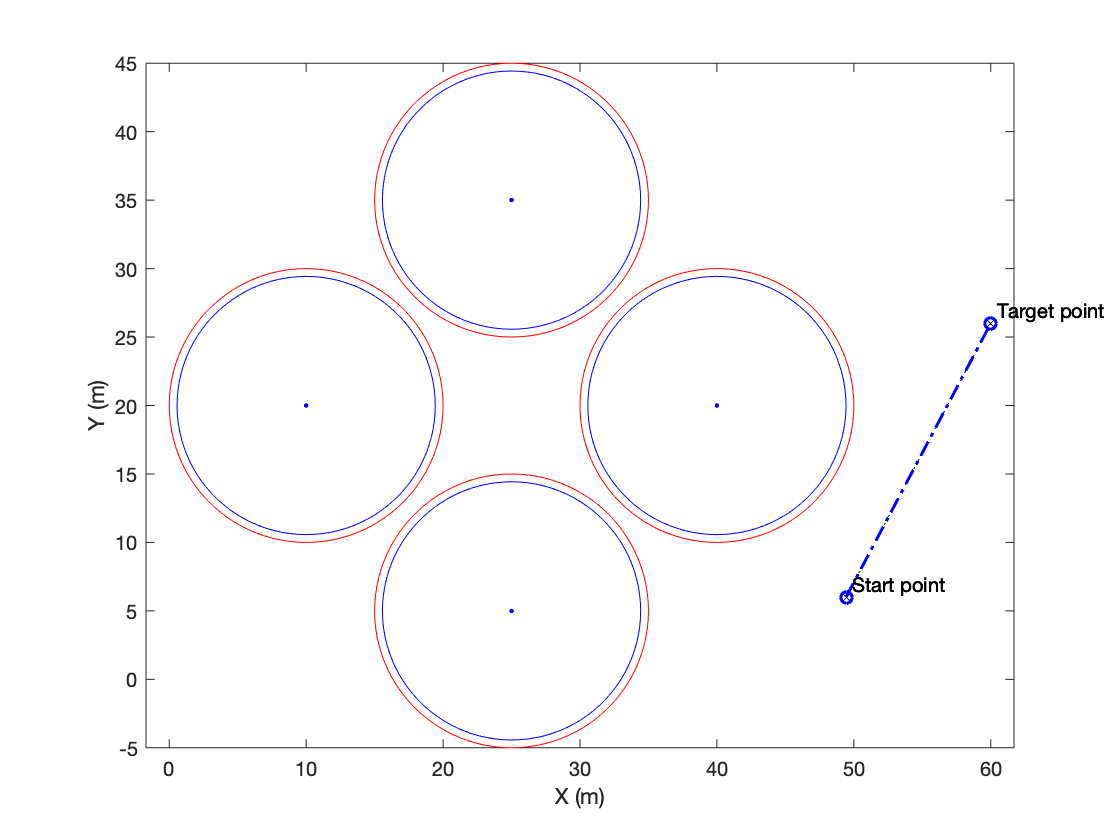

Finally


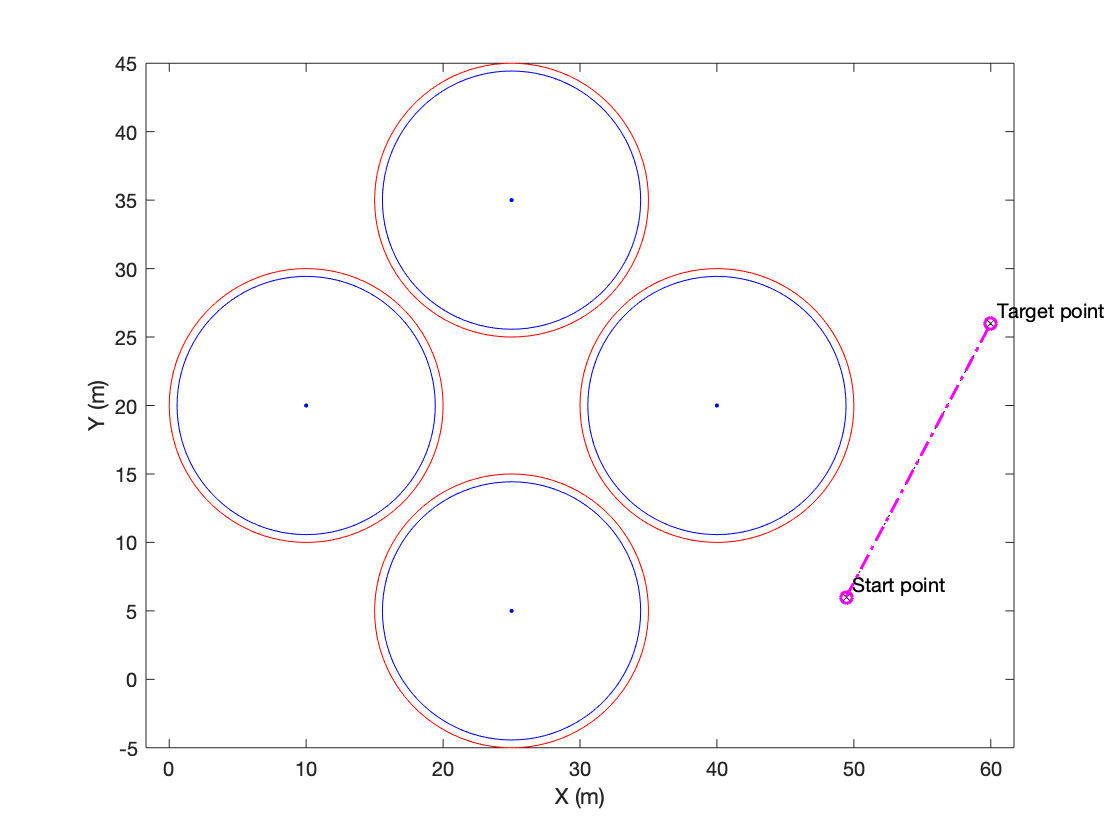

Straight-line Length: 22.6218

Minimum Trajectory No. of segments: 1
Minimum Trajectory Length: 22.6218

Simplified Trajectory No. of segments: 1
Simplified Trajectory Length: 22.6218


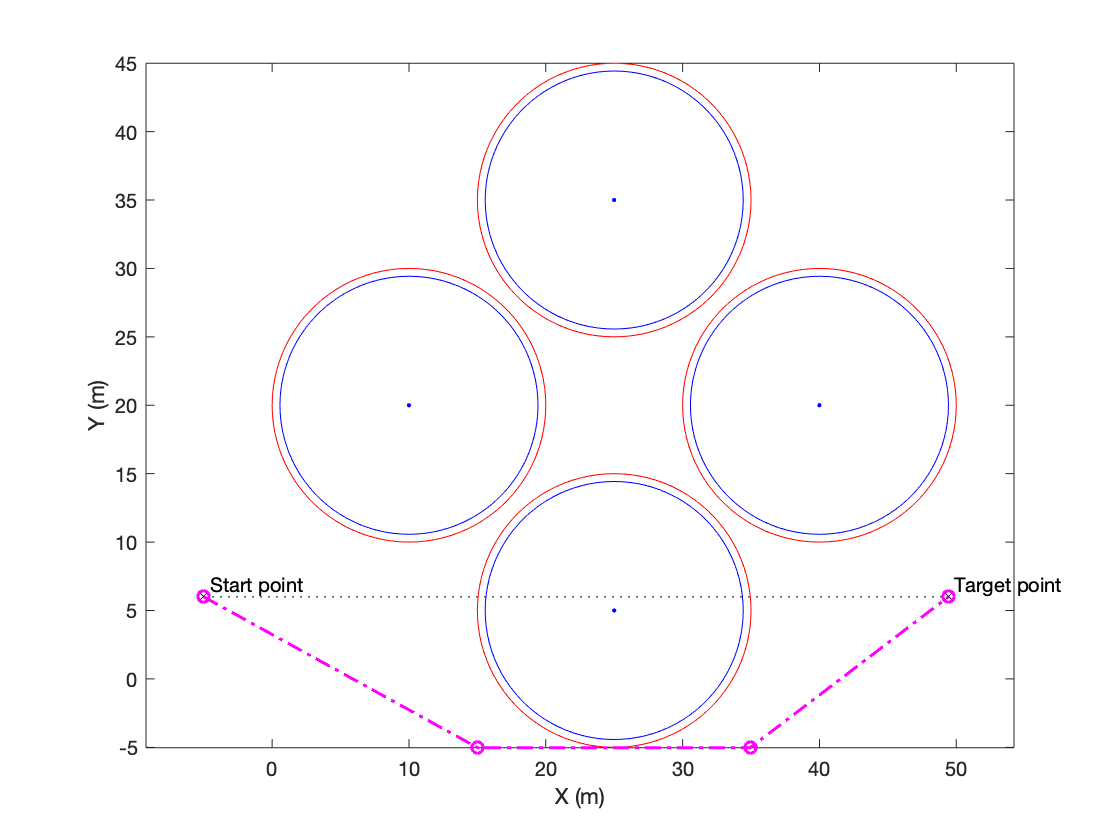

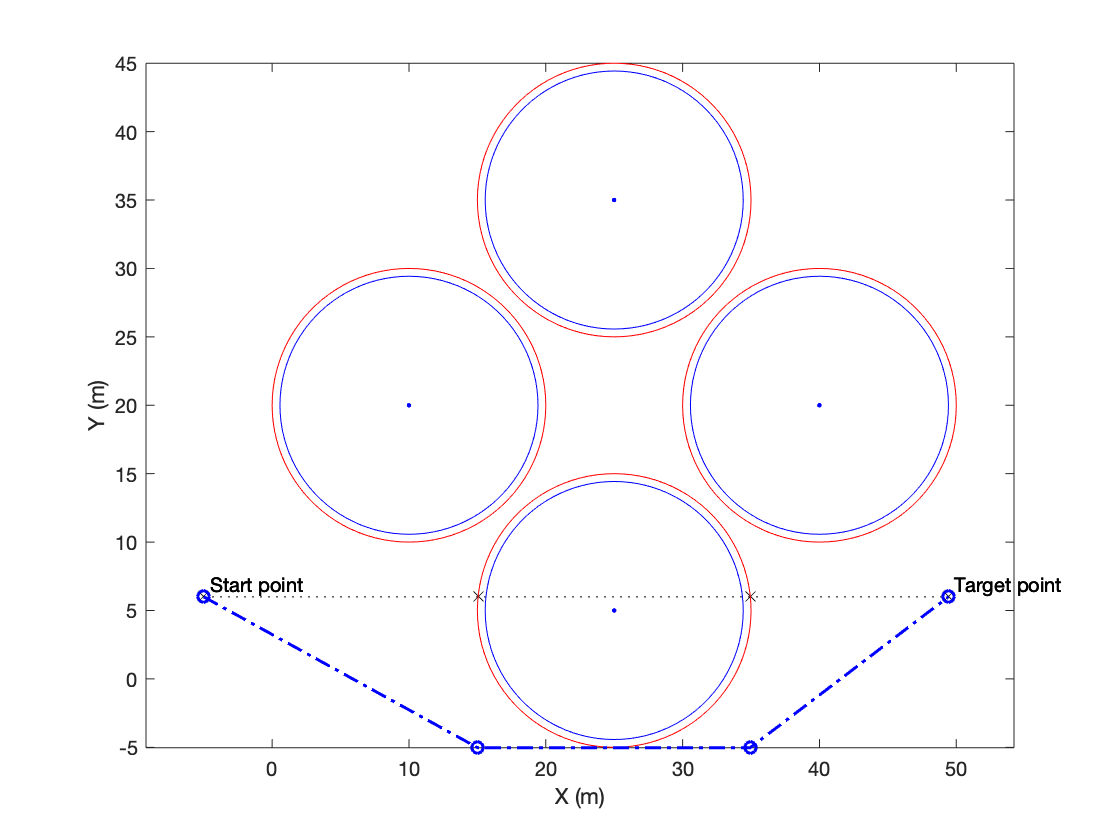

Number of virtual waypoints examined: 2


Solution found

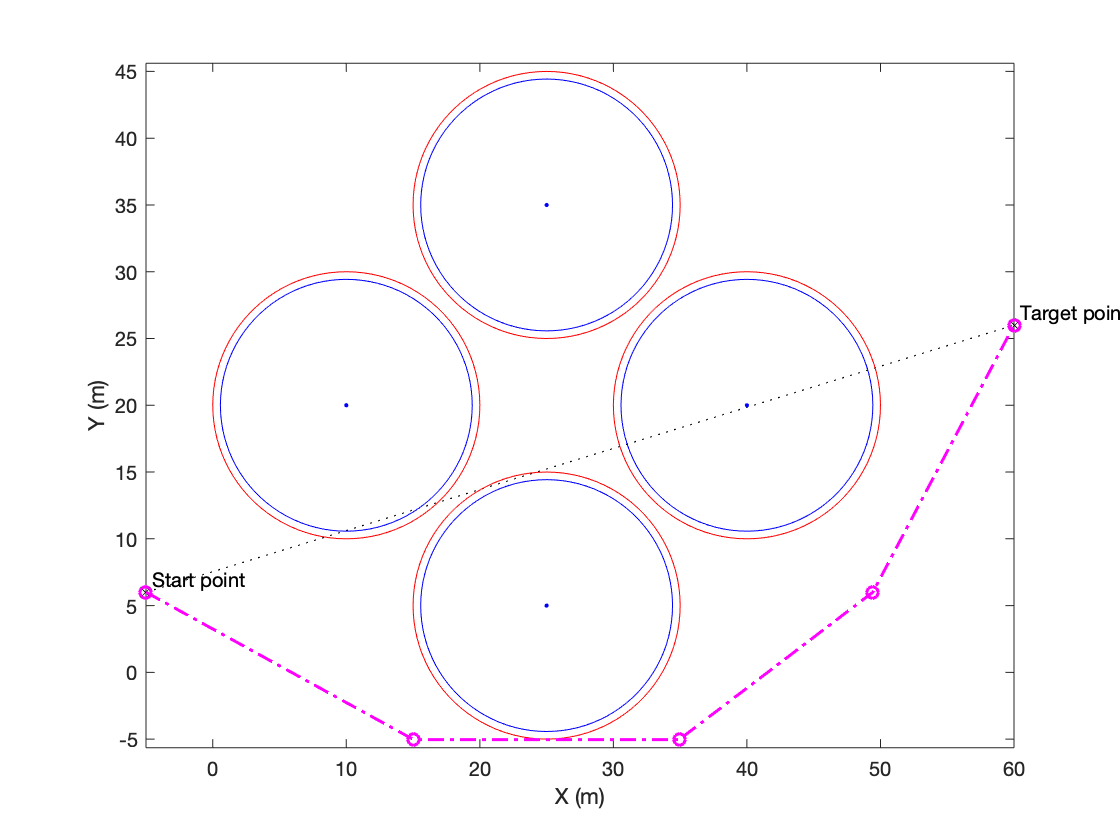

 
if (solution_found)
    return;
else
    i=1;
    
    % get the minimum x and y without radius
    % get the maximum x and y with radius
    for n = 1:length(XO)
        min_x_array(n) = XO(n) - RO(n);
        max_x_array(n) = XO(n) + RO(n);
        min_y_array(n) = YO(n) - RO(n);
        max_y_array(n) = YO(n) + RO(n);
    end
    
    min_x = min(min_x_array);
    max_x = max(max_x_array);
    min_y = min(min_y_array);
    max_y = max(max_y_array);
    
    %    find possible intermediate points
    x_intermediate = [min_x, max_x, XS, XS, min_x, max_x];
    y_intermediate = [YS, YS, min_y, max_y, min_y, max_y];
    
    while ~solution_found && i <= length(x_intermediate)
        disp('Another try:');
        disp('Intermediate point');
        disp(x_intermediate(i));
        disp(y_intermediate(i));
        Px_min = [];
        Py_min = [];
        
        % and try to make two routes
        [solution_found, err, Px_min_1, Py_min_1] = find_route(XS, YS, x_intermediate(i), y_intermediate(i), XO, YO, RO, RB, N);
        
        if (solution_found)
            [solution_found, err, Px_min_2, Py_min_2] = find_route(x_intermediate(i), y_intermediate(i), XT, YT, XO, YO, RO, RB, N);
            
            if (solution_found)
                Px_min = horzcat(Px_min_1, Px_min_2);
                Py_min = horzcat(Py_min_1, Py_min_2);
            end
        end
        
        i=i+1;
    end
    
    if (solution_found)
        fprintf('\n')
        disp(['Number of virtual waypoints examined: ' num2str(i - 1)])
        fprintf('Solution found');
        figure(1000000);
        [RD] = plot_obstacles(XS, YS, XT, YT, XO, YO, RO, RB, N);
        plot(Px_min, Py_min, '-.om', 'LineWidth', 1.5)
    end
end


toc

Elapsed time is 16.848320 seconds.
